# Quantify Leech Neural Activity Recordings

### About the Leech

The medicinal leech, [Hirudo medicinalis](https://en.wikipedia.org/wiki/Hirudo_medicinalis), is an important experimental preparation in neuroscience, contributing many insights into how nervous systems produce behaviors, including rhythmic behaviors such as swimming and heartbeat and behavioral choice [1,2].

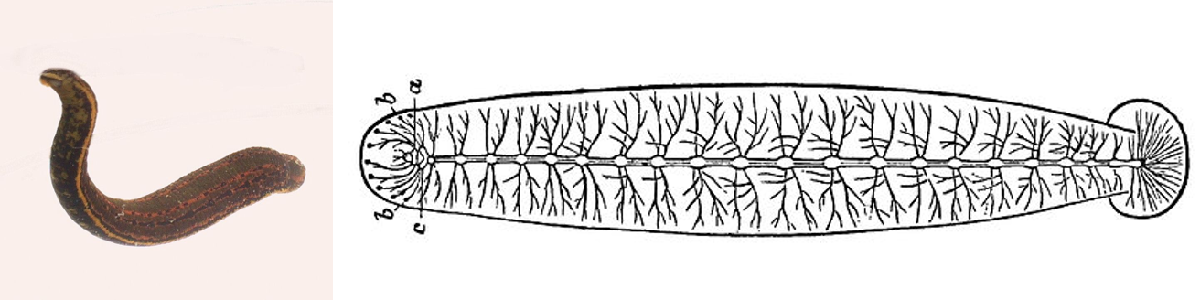

Photo credit: Karl Ragnar Gjertsen ([CC BY 2.5](https://creativecommons.org/licenses/by/2.5/))

### About the Data

The data file includes both an intracellular and extracellular recording during a single bout of (fictive) mating behavior in the leech, with some pre-computed analyses (spike detection, spike sorting). This data was collected by students in the Neural System & Behavior (NS&B) class of 2018 at Marine Biological Laboratory. 

### About this Example

This example illustrates the computation of various electrophysiological measures such as the inter-spike interval (ISI) and instantaneous firing rate (IFR), and how they can be used and even further quantified (e.g. Fano factor analysis) to characterize and compare neural activity. 

## 1. Access Data

### 1a. Load data

To begin, let's load a single session file, stored in *.mat format consisting of multiple variables:

clearvars; % clear the workspace
dataFilename = "1ex1insig_temp.mat"; 
load(fullfile('..','SampleData', 'ClassOf2018',dataFilename)); % loads three variables: tms (timebase), vlt (voltages), spks (detected spike times & amplitudes)
disp("Loaded a file of " + (tms(end)-tms(1)) + " seconds with " + size(vlt,2) + " voltage recordings");

Loaded a file of 1080 seconds with 2 voltage recordings


### 1b. Extract data

The experimental file format uses multidimensional arrays to support an arbitrary number of recordings. In this case, there are two recordings, so it's feasible to simplify our analysis by organizing related data into *structures* of vectors (single-dimensional arrays) which are easier to work with. The data filename indicates one recording is intracellular and the other extracellular, so we'll group data into two structures, one for each recording: 

% Set timebase in  milliseconds, referenced to start of time
startTime = tms(1)*1e3;
timebase = tms*1e3 - startTime;

% Create intra/extra structures for the intracellular/extracellular recordings respectively
intra.t = timebase;
intra.V = vlt(:,1);
extra.t = timebase;
extra.V = vlt(:,2);

% Pack timestamped spike data into a substructure, converted into milliseconds and referenced to time = 0
intra.spks.t = spks{1}.tms*1e3 - startTime; %convert spike timestamps into our timebase
intra.spks.V = spks{1}.amp;
extra.spks.t = spks{2}.tms*1e3 - startTime;
extra.spks.V = spks{2}.amp;

% Clear the loaded data variables; we don't need them further
clear tms vlt spks

## 2. Explore and Visualize Data

### 2a. First Look

Now let's take a first look at the recorded data, together in one plot and zoomed in so we can see the spiking structure:

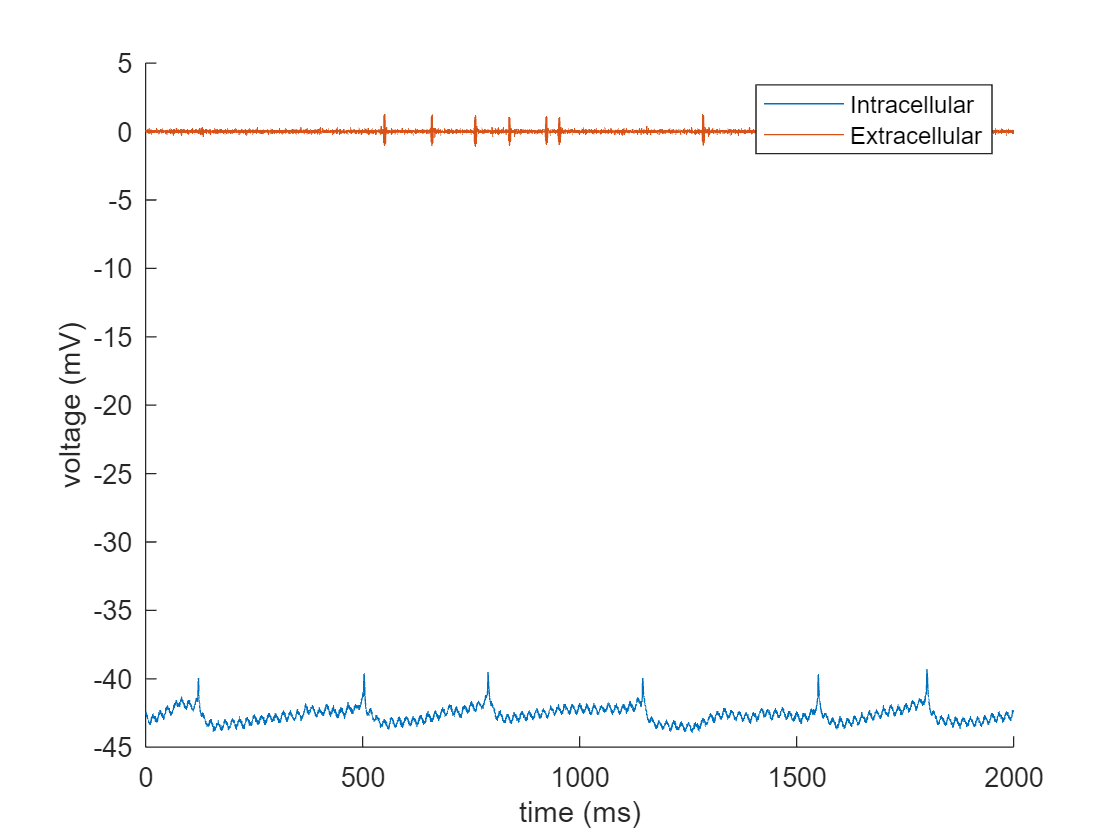

h = figure;
hold on
plot(intra.t, intra.V); %intracellular recording
plot(extra.t, extra.V); %extracellular recording
xlabel('time (ms)')
ylabel('voltage (mV)');
xlim([0 2000]); %zoom in on a 2 second window
legend(["Intracellular" "Extracellular"]);

We observe the expected differences between the intracellular and extracellular recordings (more subthreshold activity in intracellular recording). And we can observe a difference in the spiking regularity: the intracellular spikes appear fairly regularly spaced while the extracellular spikes are more bursty. 

### 2b. Highlight detected spikes

To begin to quantify the neural signals, spike detection and spike sorting (assignment of spikes to neurons) is needed. That's outside the scope of this example, but fortunately we saw these were packed along with the raw data traces in the input file. The experimentor sharing this data was keen for their data to be explored, understood, and analyzed. Let's take a look: 

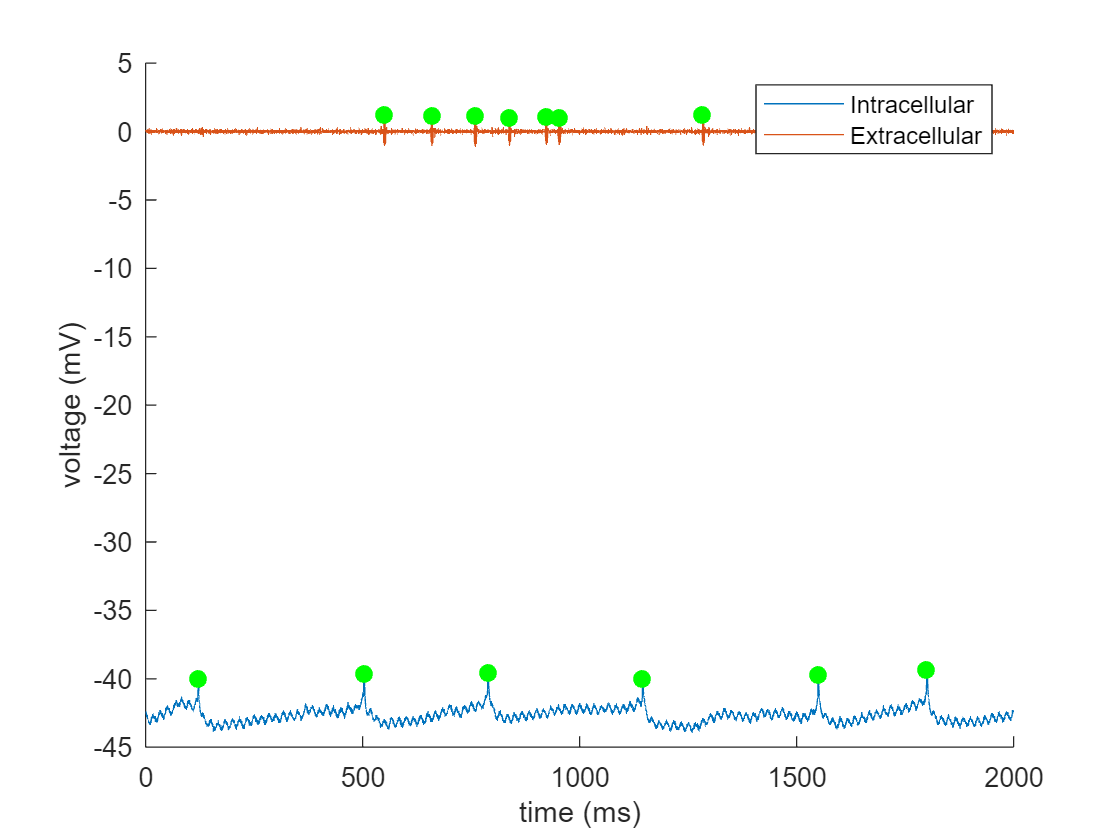

figure(h) %copy the prior figure so we can build on it 
plot(intra.spks.t,intra.spks.V,'g.','MarkerSize',20); %highlight detected spikes
plot(extra.spks.t,extra.spks.V,'g.','MarkerSize',20);
xlim([0 2000]); %zoom in on a 2 second window
legend(["Intracellular" "Extracellular"]);

The spike detection algorithm picked up all the spikes we can visually identify. With a single extracellular recording, it's assumed the spikes all correspond to a single neuron (unit) recording, so every spike in the extracellular recording is tagged as expected.

### 2c. Visualize spike train

Now that we're confident in the spike identification, we can visualize the recording as a spike train:

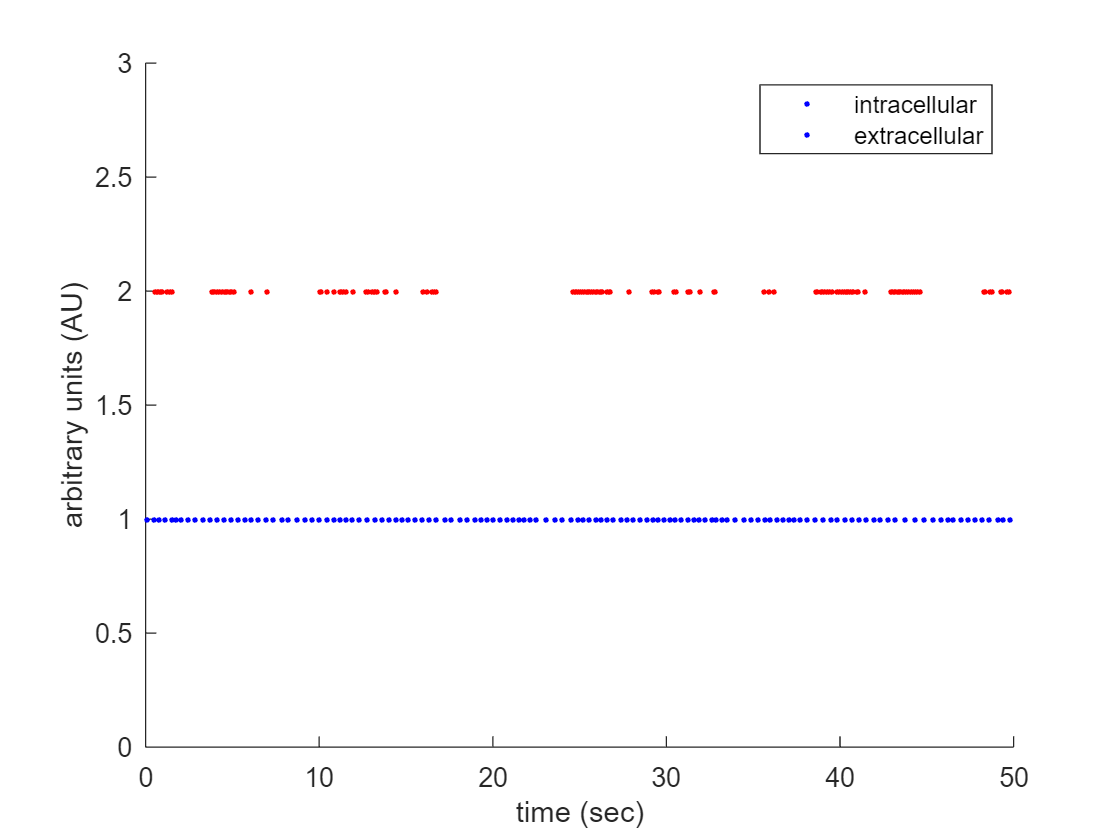

plotDuration = 50; % Duration of spiketimes to plot, in seconds

%temp vars for spike times to plot, converted to seconds
ii = intra.spks.t * 1e-3; 
ee = extra.spks.t * 1e-3; 

figure;
hold on
plot(ii(ii<=plotDuration),1,'.b'); % Plot intracellular spiketimes over specified duration, as arbitrary value 1
plot(ee(ee<=plotDuration),2,'.r'); % Plot extracellular spiketimes over specified duration, as arbitrary value 2
xlabel('time (sec)')
ylabel('arbitrary units (AU)');
legend('intracellular','extracellular');
ylim([0 3]);

Visualizing the data as a spike train further clarifies our original observation: the extracellularly-recorded neuron is spiking on a regular pattern while the intracellularly-recorded neuron fires in bursts of varying intervals. At the same time, we can see that the average firing rate of the two neurons is not too different: plotted spike trains of equal spike length span nearly equal duration. 

## 3. Compute neurophysiological measures

We've identified that our two recordings arise from two distinct neurons firing with very distinct patterns, one regular and one bursty. In these code sections, we'll quantify these distinct firing patterns using a number of standard neurophysiological measures. 

### 3a. Interspike Interval

The interspike interval (ISI) is a discrete variable, defined as the time elapsed between successive spike timestamps: 

 
$$\textrm{ISI}\left(n\right)\;=t\left(n+1\right)-t\left(n\right)$$


The `diff` command in MATLAB provides a convenient way to compute the ISI series for each recording: 

intra.spks.ISI = diff(intra.spks.t);
extra.spks.ISI = diff(extra.spks.t);

One way to quantitatively visualize the difference between the two recordings is to plot and compare the distribution of ISI values for each: 

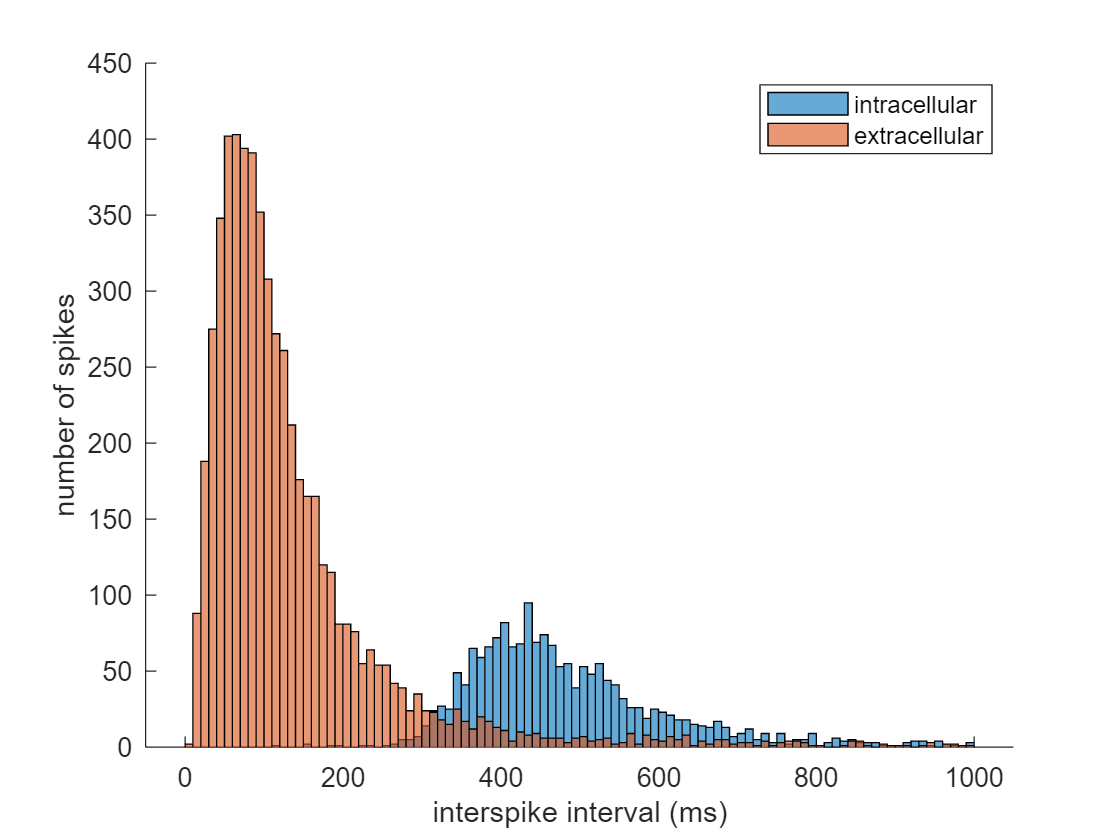

edges = 0:10:1000; %define histogram bin edges of width 10ms

figure;
hold on
histogram(intra.spks.ISI,edges);
histogram(extra.spks.ISI,edges);
xlabel('interspike interval (ms)');
ylabel('number of spikes');
legend('intracellular','extracellular');

### 3b. Instantaneous firing rate

Some neural systems and theories are better understood in terms of the frequency of spike firing, encode (e.g. the  theories of neural coding, known as rate codes, consider the frequency of spike firing. For these theories, a more relevant neurophysiological measure is the instantaneous firing rate (IFR), i.e. the neural firing rate at a given timepoint. A simple approach is to compute this value at each spike timestamp:

$\textrm{IFR}\left(t_n \right)=\frac{1}{\textrm{ISI}\left(n\right)}$.

intra.spks.IFR = 1./(intra.spks.ISI*1e-3); % Compute in spikes/sec (i.e. convert ISI from msec to sec)
extra.spks.IFR = 1./(extra.spks.ISI*1e-3);

The IFR can be plotted as a time-series using the spike timestamp series, noting that the IFR is undefined defined beyond the penultimate (second-to-last) spike given the "look-ahead" definition above.

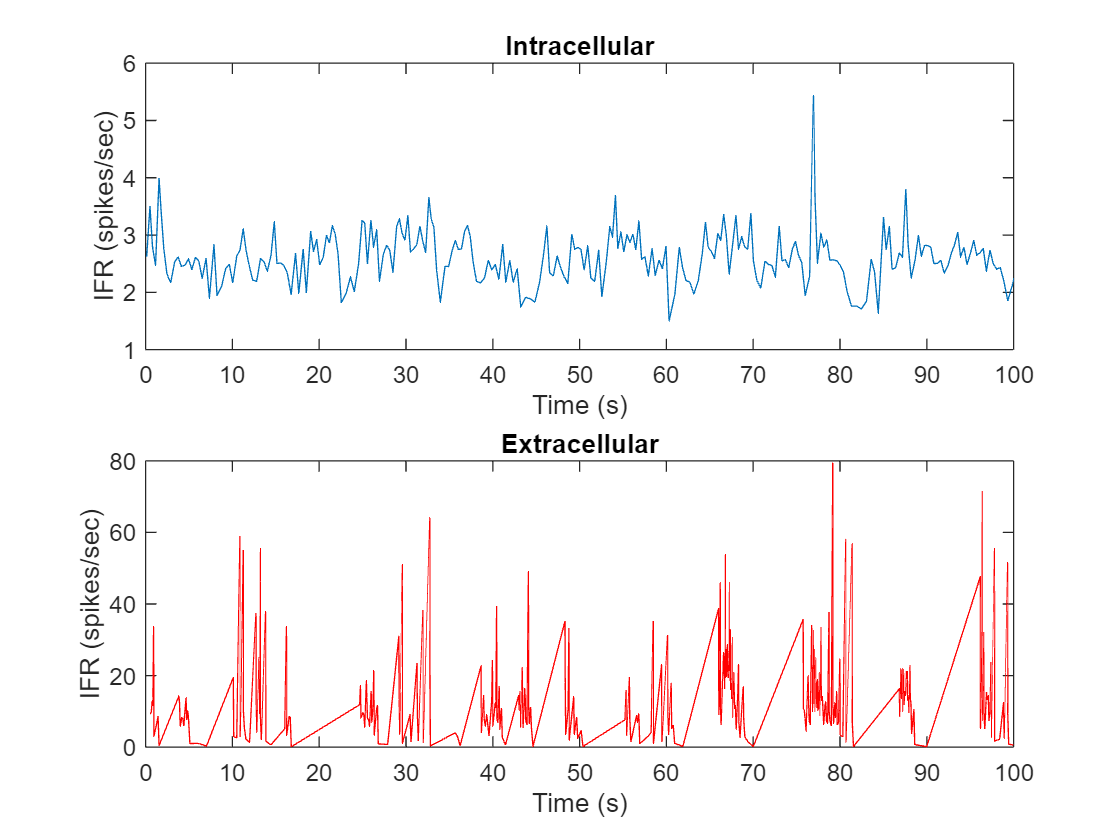

figure;
h1 = subplot(2,1,1);
plot(intra.spks.t(1:end-1)*1e-3,intra.spks.IFR); % Visualizing spike times in units of seconds
title('Intracellular');
h2 = subplot(2,1,2);
plot(extra.spks.t(1:end-1)*1e-3,extra.spks.IFR,'Color','r');
title('Extracellular');

%Use "dot" and set() operations to update both subplots together
set([h1 h2],'XLim',[0 100]); % Zoom in on a 100 second window
set([h1.XLabel h2.XLabel],'String','Time (s)'); % Drill down to a second-level property to set the axes labels
set([h1.YLabel h2.YLabel],'String','IFR (spikes/sec)');

The IFR plot reveals the regular firing of the intracellular neuron at a low firing rate (~3 spikes/sec), varying only within a narrow range, while the bursty extracellular neuron reaches higher rates (10s of spikes/sec) but only for short patches of time. 

However we see a clear artifact for the extracellular recording plot. Because the IFR is only defined at the spike timestamps and we're displaying a line plot (to show the evolution of the firing rate over time), the inter-burst periods appear as discontinuities.

A method to overcome this is to remap the IFR time series to the original recording timebase. This includes "filling in" the IFR value for all timebase values using the last-known value, to better represent quiescent periods between bursts. For this remapping, the timestamps must also be aligned to the timebase.  A documented helper function located at the bottom of this file computes the remapping: 

intra.IFR = timestamp2Timebase(intra.t,intra.spks.t(1:end-1),intra.spks.IFR);
extra.IFR = timestamp2Timebase(extra.t,extra.spks.t(1:end-1),extra.spks.IFR);

Visualizing the IFR on the recording timebase removes the discontinuities and represents the inter-burst windows in the extracellular recordings as zero-valued IFR: 

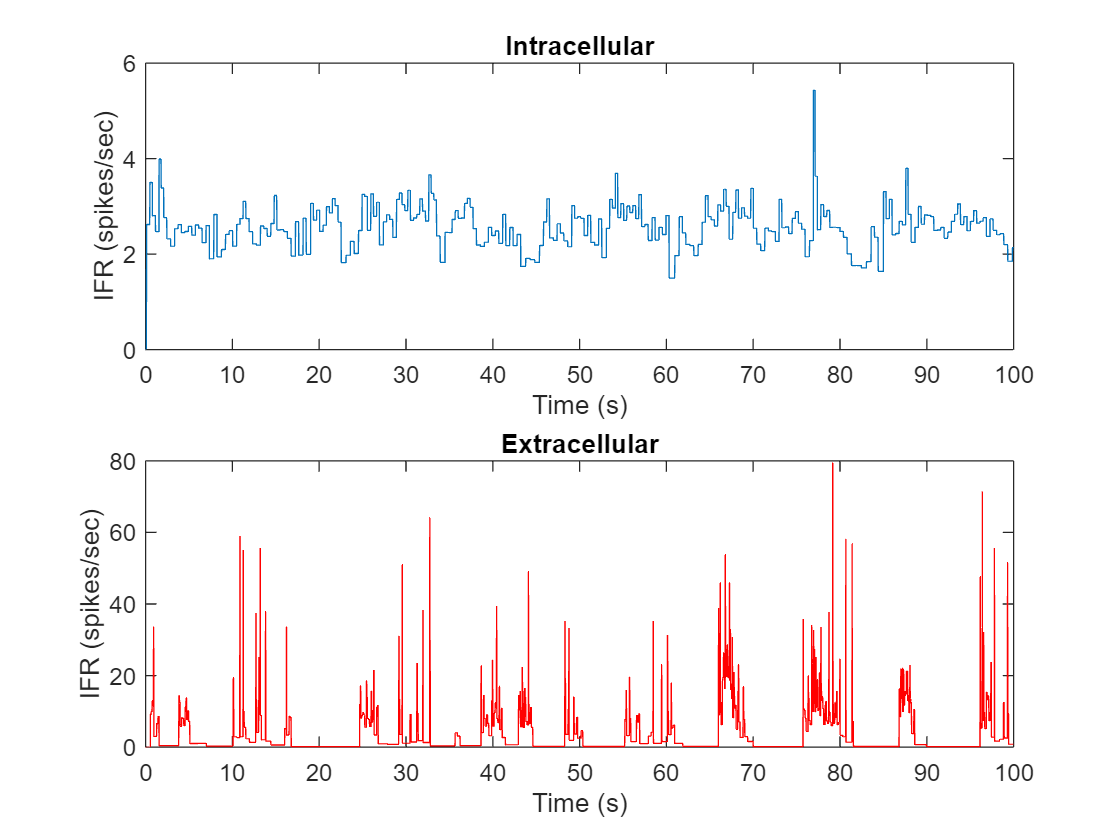

figure;
h1 = subplot(2,1,1);
plot(intra.t*1e-3,intra.IFR);
title('Intracellular');
h2 = subplot(2,1,2);
plot(extra.t*1e-3,extra.IFR,'Color','r');
title('Extracellular');
set([h1 h2],'XLim',[0 100]); % Zoom in on a 100 second window
set([h1.XLabel h2.XLabel],'String','Time (s)');
set([h1.YLabel h2.YLabel],'String','IFR (spikes/sec)');

Coding challenge: Refactor the IFR plotting code into a local function that is called to plot both the original and remapped IFR plot pairs

### 3c. Binned instantaneous firing rate

The IFR time-series are rather noisy with several short-lived time transients, which rate code theories and interpretations wouldn't be concerned with. Another approach to reveal the rate trajectory of a neural recording at a coarser scale is to count the number of spikes within a given time bin and compute the average firing rate therein. This can be expressed as: 

$\textrm{IFR}\left(k\right)=\frac{N\left(k\right)}{W}$ where $N\left(k\right)$is the number of spikes in timebin $k$ and $W$is the timebin width. 

This involves computing histograms for each spike timestamp record, but we don't actually need to plot it. This can be done with the `histcounts` function (which underlies the `histogram` plotting function we used above):

binWidth = 1000; %in ms

% Count the number of spikes in each timebin
maxTimestamp = max(max(intra.spks.t),max(extra.spks.t)); % determine the largest timestamp across each of the recordings
[int_counts,intra.tIFR_bin] = histcounts(intra.spks.t,0:binWidth:maxTimestamp);
[ext_counts,extra.tIFR_bin] = histcounts(extra.spks.t,0:binWidth:maxTimestamp);

We can then convert to binned IFR values by dividing by the bin width $W\;$ (`binWidth`). Since the bin edges are common between the two recordings, we can plot them on a common x-axis using `stackedplot:`

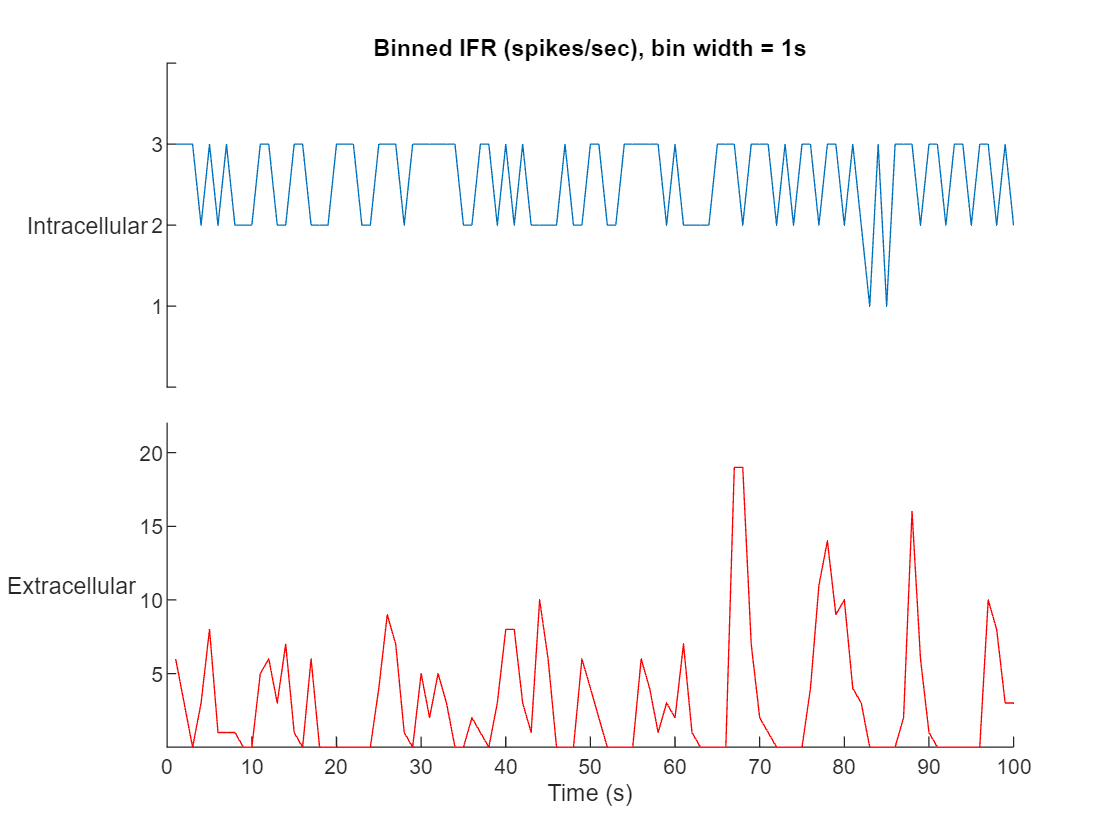


% Convert counts to IFR values (in spikes/sec) for each timebin
intra.IFR_bin = int_counts/(binWidth * 1e-3); % Convert to spikes/sec (i.e. msec to sec)
extra.IFR_bin = ext_counts/(binWidth * 1e-3);

% Plot the binned IFRs as a stacked plot
figure;
assert(isequal(intra.tIFR_bin,extra.tIFR_bin), 'The intracellular and extracellular timebin vectors should be equal'); %stacked plots must share a common x-axis vector
s = stackedplot(intra.tIFR_bin(2:end) * 1e-3,[intra.IFR_bin' extra.IFR_bin']); %Convert to seconds
s.Title = "Binned IFR (spikes/sec), bin width = " + binWidth * 1e-3 + "s";
s.XLabel = 'Time (s)';
s.XLimits = [0 100]; %Zoom to a 100 second window
s.DisplayLabels = ["Intracellular" "Extracellular"];
s.LineProperties(2).Color = 'r';

The binned IFR approach removes the spikiness of the unbinned IFR and reveals how regular the intracellular IFR is between 2 and 3 spikes/sec. 

The `binWidth `is a parameter of the binned IFR measure. Adjusting the slider above, we can see that Increasing the `binWidth` value gradually attenuates (filters) the maximum detectable IFR values. At the extreme, a binWidth equal to the recording length would limit the IFR to the average firing rate. This filtering effect can be seen clearly for the extracellular binned IFR. Fundamentally, the notion of "instantaneous frequency" is subjective as to what "instantaneous" means and this is subjectivity is expressed through the `binWidth parameter`. 

## 4. Compute statistical metrics

The neurophysiological measures we've computed above were presented as stastical distributions or computed time-series. They represented the recordings in more compact ways to better capture our initial impression of two distinctly firing cells, one firing regularly and the other firing in bursts. We could take this a step further to quantify a single numeric metric based on statistics of the computed measures above. 

### 4a. IFR Fano factor

For example, the [Fano factor](http://%20%20https//en.wikipedia.org/wiki/Fano_factor) is a statistical metric for time-binned data,  

$F=\frac{\sigma ²_W }{\mu_W }$ ,

where $\sigma_W^2$ and $\mu_W$ are the variance and mean of a time-series within a timebin of width$W$. We can compute the Fano factor for the binned IFR values we computed above:

int_IFR_Fano = var(intra.IFR_bin)/mean(intra.IFR_bin);
ext_IFR_Fano = var(extra.IFR_bin)/mean(extra.IFR_bin);

disp("IFR Fano Factor (intracellular): " + int_IFR_Fano);

IFR Fano Factor (intracellular): 0.42402


disp("IFR Fano Factor (extracellular): "  + ext_IFR_Fano);

IFR Fano Factor (extracellular): 3.7193


How do we interpret these Fano factors? Events occurring with some probability distribution over time are often compared in reference to the [Poisson distribution](https://en.wikipedia.org/wiki/Poisson_distribution), which has the property where the mean and variance of events occurring within a time window are equal. In other words, the Fano factor of a Poisson process equals 1. A Poisson distribution arises when each event occurs at some fixed probability and strictly independently of other events. We know this is not the case for a neuron firing, because of biophysical phenomena like the spike refractory period and cellular excitability. 

Computed Fano factors can be regarded as either sub-Poissonian ($\left.F<1\right)$or super-Poissonian $\left(F>1\right)$, corresponding to the cases where the occurrence of an event makes an immediately succeeding event less or more likely, respectively. How does this map to neural firing pattens? Regularly firing neurons will be sub-Poissonian (a quiet period follows each spike) whereas bursting neurons will be super-Poissonian (a spike indicates the likelihood of a burst window, i.e. a higher spike probability). 

Indeed, that's what we see computed for our dataset: the regular intracellular recording is sub-Poissonian  ($\left.F<1\right)$ and the bursty extracellular recording is super-Poissonian  ($\left.F\;>1\right)$. 

### 4b. IFR Fano factor bin width effects

As we observed earlier, the binned instantaneous firing rate (IFR) depends on the bin width at which it's computed. How does this impact the binned IFR Fano factor metric? 

binWidths = [200 500 1000 2000 5000 10000]; %msec

% Initialize a summary table of computed Fano values at variable bin widths
summary.IFR_Fano = table();
summary.IFR_Fano.BinWidth_msec = binWidths';

% Compute Fano factor for each recording at each bin width and add rows to table 
for ii=1:length(binWidths)
    
    % Compute counts in each timebin
    int_counts = histcounts(intra.spks.t,0:binWidths(ii):maxTimestamp); % compute intracellular smoothed IFR
    ext_counts = histcounts(extra.spks.t,0:binWidths(ii):maxTimestamp); % compute extracellular smoothed IFR
    
    % Convert counts to IFR values (in spikes/sec) for each timebin
    int_IFR_binned = int_counts/(binWidths(ii) * 1e-3); % Convert to spikes/sec (i.e. msec to sec)
    ext_IFR_binned = ext_counts/(binWidths(ii) * 1e-3);
    
    % Compute the binned IFR Fano factor
    int_Fano = var(int_IFR_binned)/mean(int_IFR_binned);
    ext_Fano = var(ext_IFR_binned)/mean(ext_IFR_binned);
    
    %Add new variables to the summary table
    summary.IFR_Fano.Intracellular(ii) = int_Fano;
    summary.IFR_Fano.Extracellular(ii) = ext_Fano;
end

disp(summary.IFR_Fano);

    BinWidth_msec    Intracellular    Extracellular
    _____________    _____________    _____________

          200            3.2528           5.7724   
          500           0.68836           4.3579   
         1000           0.42402           3.7193   
         2000           0.32937           2.9621   
         5000           0.27129           1.5546   
        10000           0.24538          0.71224   



While the Fano factors vary with bin width, generally we see the same picture: the intracellular Fano factor reflects a sub-Poissonian process (regular firing neuron) and the extracellular Fano factor reflects a super-Poissonian process (bursting neuron). However, we do see some variation in the values with bin width and notably these core findings break down at the smallest and largest bin widths. 

Why so? 

- Short bin widths will only have up to 1 spike per bin (i.e. there's no possibility for two spikes in such a small interval). The binned IFR in these cases will be computed as $\left(\frac{1}{W}\right)$, i.e. determined by the (small) bin width $W$regardless of the actual underlying firing rate. Thus the IFR is artificially high for these bins. Meanwhile, all other time bins will have zero spikes and hence a computed IFR value of 0, i.e. IFR values which are artificially low. Put together, the IFR variance is artificially increased and hence the Fano factor increases regardless of the underlying spike event statistics. . 

- Long bin widths filter IFR values (as we saw above), reducing the variance and hence the Fano factor. This filtering effect particularly affects the high-IFR bursting extracellular neuron.

Lesson learned: to meaningfully compare the Fano factors between two recordings, it's important to use a bin factor that avoids such artifacts. Practically, we can choose to limit the filtering effects by using the shortest bin width possible without incurring the short bin artifact. For instance, we can use a value of 1000 millesconds (as above), which avoids this artifact for neurons with an average (and regular) firing rate >2 spikes/sec range (i.e. an average of 2 or more spikes per bin).  

## 5. Recap and Saving Results

In this example, two clearly distinct neuronal firing patterns (regular spiking and bursting) were observed in the original recordings. We've explored how various measures can be used to quantitatively characterize and compare these recordings. They've confirmed our original observations (when used and interpreted correctly).

The measures and metrics we've computed (ISI, IFR, binned IFR, IFR Fano factor) have added value to the dataset. They provide a means to express and communicate the results compactly to colleagues, i.e. without requiring them to browse the full raw recordings to understand them "by inspection". They provide a connection to various theoretical approaches (e.g. IFRs for rate code theories). And these compact quantifications will become increasingly essential for further studies where the number of recordings increases, both within a single session and across sessions. 

Finally, what should we do with our results? Others might want to explore and build on these measures and findings. During this work, we've packed both the original dataset and the computed values into three structure variables (`intra,extra,summary)`. Let's output these into a new file which can be shared with interested colleagues: 

[filepath, name, ext] = fileparts(dataFilename);
save(fullfile(filepath, name + "_analyzed" + ext),'intra', 'extra','summary','-mat');

## References

[[1](https://jeb.biologists.org/content/218/21/3353)] Daniel A Wagenaar. A classic model animal in the 21st century: recent lessons from the leech nervous system. *Journal of Experimental Biology *2015. 

[2] William B. Kristan, Ronald L. Calabrese, and W. Otto Friesen. Neuronal control of leech behavior. *Progress in Neurobiology* 2005.

## Helper Functions

function vals_timebased = timestamp2Timebase(timebase,evnt_timestamps,val_timestamped)
% Map event-timestamped values to a timebase vector, aligning timestamps to timebase and filling-in intervals between timestamps
% Inputs
%   timebase: timebase vector to map event data onto
%   evnt_timestamps: vector of timestamps at which events occurred (in same units as timebase)
%   val_timestamped: vector of values aligned to each of the timestamped events 
%
% Notes:
%  1. Tolerance of time alignment is at 1 ppm (10^-6) relative to the timestamp/timebase units
%  2. Timebase fill-in between events uses "hold last value" approach
%    

TOL= 1e-6; % Hard-coded constant for time-alignment tolerance

% Initialize output vector on the supplied timebase 
vals_timebased = zeros(length(timebase),1);

% Alignment: Identify the timebase timepoint (index) corresonding to each event timestamp
numTimestamps = length(evnt_timestamps);
timebaseIdxs = zeros(numTimestamps,1);
for ii=1:numTimestamps
    timebaseIdxs(ii) = find(abs(timebase - evnt_timestamps(ii)) < TOL); % Find the timebase timepoint equal to tiemstamp to within the specified toleratnce
end 

% Map with fill-in: Assign timestamped values to recording timebase, starting at the corresponding timepoint and filling-in with same value until the next event timestamp
for ii=1:(numTimestamps-1)
    vals_timebased(timebaseIdxs(ii):timebaseIdxs(ii+1)) = val_timestamped(ii);
end

end